Sistema Doble Amortiguado 

clc
clear
close all

## Parametros

m1=2;
m2=3;
k1=20;
k2=15;
k3=10;
c1=2;
c2=1.5;

## Matriz del sistema


A = [ 0               1               0               0;
     -(k1+k3)/m1    -c1/m1          k3/m1            0;
      0               0               0               1;
      k3/m2           0           -(k2+k3)/m2      -c2/m2 ];
 

## Valores propios


autovalores = eig(A);

## Condiciones iniciales

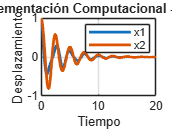


  x0= [1; 0; 1; 0]; 
%%intervalo de tiempo

tspan=[0,20];
%% Solución numérica

[t,X] = ode45(@(t,x) A*x, tspan, x0);
%% Graficas

figure
plot(t,X(:, 1), 'LineWidth',2)
hold on
plot(t,X(:,3),'LineWidth',2)
legend('x1','x2')
xlabel('Tiempo')
ylabel('Desplazamiento')
title ('Implementación Computacional - Caso #4')
grid on